clear all
close all

% Numercial Expressions

DH = [      0        0       0       0;     %alpha, a, d, theta
            -pi/2     0       0.2435      0;
            0       0.4318      -0.0934      pi;
            pi/2    -0.0203      0.4331      0;
            -pi/2   0       0       0;
            pi/2    0       0       0
        ]

DH =          0         0         0         0
   -1.5708         0    0.2435         0
         0    0.4318   -0.0934    3.1416
    1.5708   -0.0203    0.4331         0
   -1.5708         0         0         0
    1.5708         0         0         0



T_01 = transformationMatrix(DH(1,:));
T_12 = transformationMatrix(DH(2,:));
T_23 = transformationMatrix(DH(3,:));
T_34 = transformationMatrix(DH(4,:));
T_45 = transformationMatrix(DH(5,:));
T_56 = transformationMatrix(DH(6,:));
T_6T = [    1       0       0       -0.1;
            0       1       0       0;
            0       0       1       0.13625;
            0       0       0       1]

T_6T =     1.0000         0         0   -0.1000
         0    1.0000         0         0
         0         0    1.0000    0.1363
         0         0         0    1.0000



T_06 = T_01*T_12*T_23*T_34*T_45*T_56

T_06 =    -1.0000   -0.0000    0.0000    0.4521
    0.0000    1.0000    0.0000    0.1501
   -0.0000    0.0000   -1.0000   -0.4331
         0         0         0    1.0000


T_0T = T_06*T_6T

T_0T =    -1.0000   -0.0000    0.0000    0.5521
    0.0000    1.0000    0.0000    0.1501
   -0.0000    0.0000   -1.0000   -0.5694
         0         0         0    1.0000


T_T6 = (T_6T)^(-1)

T_T6 =     1.0000         0         0    0.1000
         0    1.0000         0         0
         0         0    1.0000   -0.1363
         0         0         0    1.0000


% Intial Configuration
T_initial = FKPuma([0 0 pi 0 0 0])

T_initial =    -1.0000   -0.0000    0.0000    0.4521
    0.0000    1.0000    0.0000    0.1501
   -0.0000    0.0000   -1.0000   -0.4331
         0         0         0    1.0000


 FKPuma([0 0 0 0 pi/2 0])

ans =     0.0000   -0.0000    1.0000    0.4115
    0.0000    1.0000    0.0000    0.1501
   -1.0000    0.0000    0.0000    0.4331
         0         0         0    1.0000


T0_temp = FKPuma([0 -pi/2 3.5*pi/4 0 0 0])

T0_temp =     0.3827   -0.0000    0.9239    0.3924
    0.0000    1.0000    0.0000    0.1501
   -0.9239    0.0000    0.3827    0.6163
         0         0         0    1.0000


[R0_temp, P0_temp] = tr2rt(T0_temp);
R0 = [  0 1 0;
        0 0 1;
        1 0 0];
T0 = rt2tr(R0, P0_temp)

T0 =          0    1.0000         0    0.3924
         0         0    1.0000    0.1501
    1.0000         0         0    0.6163
         0         0         0    1.0000


IKPuma(T0, 0.4318, -0.0203, 0.2435, -0.0934, 0.4331)

ans =    -0.0000   -1.5708    2.7489    1.5708    1.5708   -1.1781
   -0.0000   -0.4369    0.4864    1.5708    1.5708   -0.0494
   -2.4108   -2.7047    2.7489    0.8405    1.5413    0.0329
   -2.4108   -1.5708    0.4864    1.1741   -0.9397   -0.9534


% This the common corner point of the cube. This will be considered
% origin to find other points
T0_corner = T0*T_6T

T0_corner =          0    1.0000         0    0.3924
         0         0    1.0000    0.2863
    1.0000         0         0    0.5163
         0         0         0    1.0000


[R0_corner, P0_corner] = tr2rt(T0_corner);
P_now = [0; 0; 0];
theta1 = IKPuma2(P_now, P0_corner, 0.4318, -0.0203, 0.2435, -0.0934, 0.4331, 1)

theta1 =    -0.0000   -1.5708    2.7489    1.5708    1.5708   -1.1781


P = [];
positionError = [];
orientationError = [];

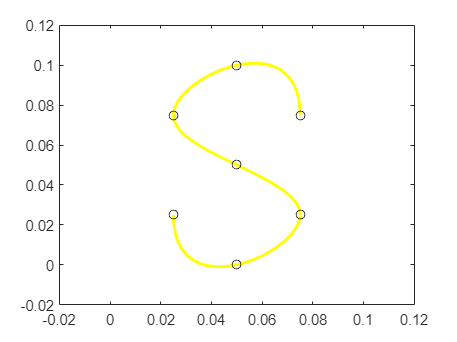

% First Letter (S)
Sxy = [ 0.075, 0.075;
        0.05, 0.1;
        0.025, 0.075;
        0.05, 0.05;
        0.075, 0.025;
        0.05, 0;
        0.025, 0.025];

ax_lim_s = [-0.02 0.12 -0.02 0.12];

[sx, sy] = plotLetter(Sxy, 200, ax_lim_s);

% Phase 1: Corner Point to Start of First Letter Transition 1
Tr1xy = [0, 0;
         sx(1), sy(1)];
[tr1x, tr1y] = plotLines(Tr1xy, 50);

theta1 = [];
theta0 = [0 0 pi 0 0 0];
theta_corner = IKPuma3([0; 0; 0], P0_corner, 0.4318, -0.0203, 0.2435, -0.0934, 0.4331, 1)

theta_corner =    -0.0000   -1.5708    2.7489    1.5708    1.5708    1.9635


theta1 = [theta1; JSTrajectory2(theta0, theta_corner, 50)];

for i=1:length(tr1x)
    Px = tr1x(i); Py = tr1y(i); Pz = 0;
    P_now = [Px; Py; Pz];
    theta_now = IKPuma3(P_now, P0_corner, 0.4318, -0.0203, 0.2435, -0.0934, 0.4331, 1);
    theta1 = [theta1; theta_now];
    P = [P P_now];
    [positionErrorNow, orientationErrorNow] = calculatePositionError(theta_now, P_now, P0_corner, 1);
    positionError = [positionError, positionErrorNow];
    orientationError = [orientationError, orientationErrorNow];
end

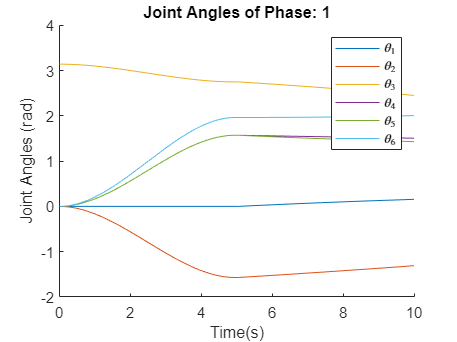

The amount of via points used in this Phase is: 100

time1 = 10;
time = plotThetas(theta1, time1, 1);

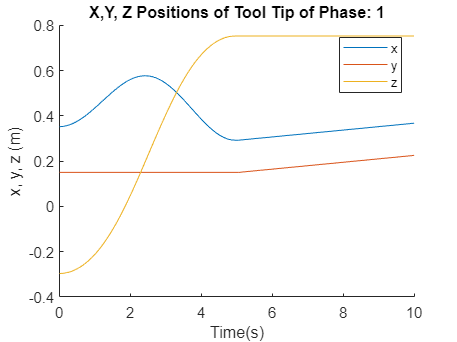

plotxyz(theta1, time1, 1);

% Phase 2 : Trace the first letter
theta2 = [];
for i=1:length(sx)
    Px = sx(i); Py = sy(i); Pz = 0;
    P_now = [Px; Py; Pz];
    theta_now = IKPuma3(P_now, P0_corner, 0.4318, -0.0203, 0.2435, -0.0934, 0.4331, 1);
    theta2 = [theta2; theta_now];
    P = [P P_now];
    [positionErrorNow, orientationErrorNow] = calculatePositionError(theta_now, P_now, P0_corner, 1);
    positionError = [positionError, positionErrorNow];
    orientationError = [orientationError, orientationErrorNow];
end

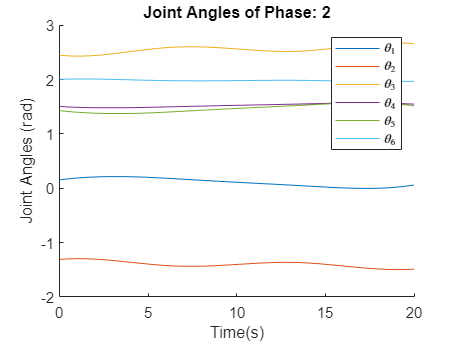

The amount of via points used in this Phase is: 200

% Plot all joint angles of phase 2
time2 = 20;
time_prev = time(end);
time = [time, plotThetas(theta2, time2, 2) + time_prev];

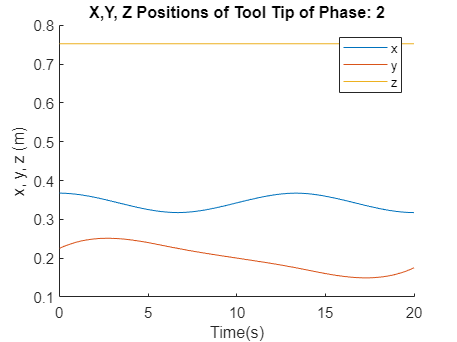

plotxyz(theta2, time2, 2);

% Second Letter: B
Bxy_straight_1 = [ 0.1, -0.05; 
                    0.1, 0;
                    0.05, 0;
                    0.025, 0];
Bxy_spline = [   0.025, 0
                 0, -0.025;
                 0.025, -0.05;
                 0, -0.075;
                 0.025, -0.1];
Bxy_straight_2 = [ 0.025, -0.1;
                    0.1, -0.1;
                    0.1, -0.05];


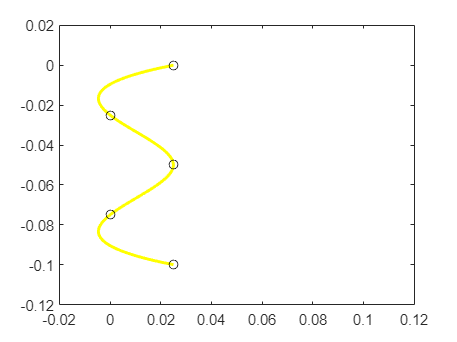

ax_lim_b = [-0.02 0.12 -0.12 0.02];

[bx_1, by_1] = plotLines(Bxy_straight_1, 50);
[bx_2, by_2] = plotLetter(Bxy_spline, 100, ax_lim_b);

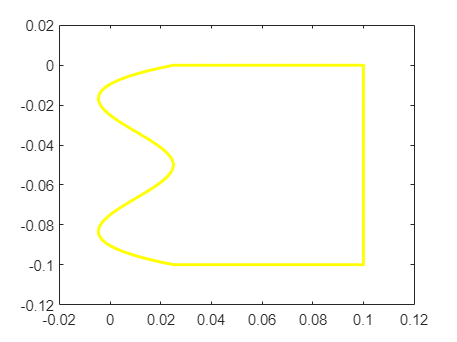

[bx_3, by_3] = plotLines(Bxy_straight_2, 50);
bx = [bx_1, bx_2, bx_3];
by = [by_1, by_2, by_3];
plotScript(bx, by, ax_lim_b);

%Phase 3: Transition from letter S to B
Tr3xy1 = [sx(end), sy(end);
         0, 0];
[tr3x1, tr3y1] = plotLines(Tr3xy1, 50);

theta3 = [];
for i=1:length(tr3x1)
    Px = tr3x1(i); Py = tr3y1(i); Pz = 0;
    P_now = [Px; Py; Pz];
    theta_now = IKPuma3(P_now, P0_corner, 0.4318, -0.0203, 0.2435, -0.0934, 0.4331, 1);
    theta3 = [theta3; theta_now];
    P = [P P_now];
    [positionErrorNow, orientationErrorNow] = calculatePositionError(theta_now, P_now, P0_corner, 1);
    positionError = [positionError, positionErrorNow];
    orientationError = [orientationError, orientationErrorNow];
end

theta3 = [theta3; JSTrajectory1(1, 2, P0_corner, 50)];

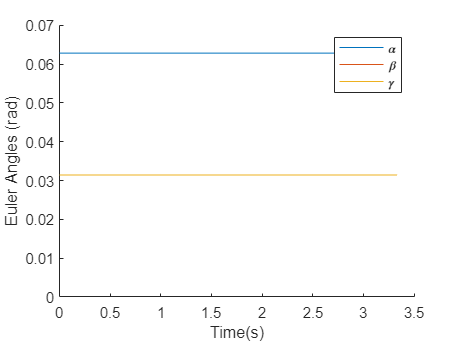

plotEulerAngles(1,2, 10/3); 

% Euler angles are plotted only where euler angles are changing. Rest
% everywhere they are 0.

Tr3xy2 = [0, 0;
         bx(1), by(1)];
[tr3x2, tr3y2] = plotLines(Tr3xy2, 50);

for i=1:length(tr3x2)
    Px = 0; Py = tr3x2(i) ; Pz = tr3y2(i);
    P_now = [Px; Py; Pz];
    theta_now = IKPuma3(P_now, P0_corner, 0.4318, -0.0203, 0.2435, -0.0934, 0.4331, 2);
    theta3 = [theta3; theta_now];
    P = [P P_now];
    [positionErrorNow, orientationErrorNow] = calculatePositionError(theta_now, P_now, P0_corner, 2);
    positionError = [positionError, positionErrorNow];
    orientationError = [orientationError, orientationErrorNow];
end

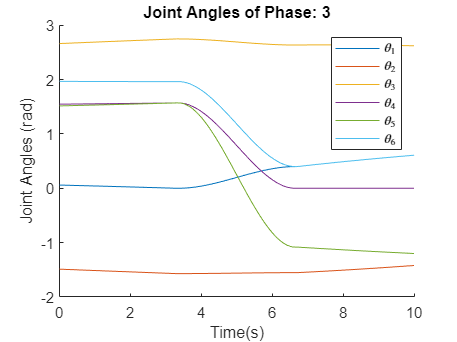

The amount of via points used in this Phase is: 150

time_prev = time(end);
time = [time, plotThetas(theta3, 10, 3)+time_prev];

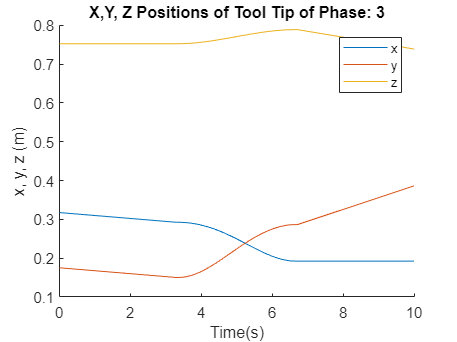

plotxyz(theta3, 10, 3);

% Phase 4 : Trace the second letter B
theta4 = [];
for i=1:length(bx)
    Px = 0; Py = bx(i); Pz = by(i);
    P_now = [Px; Py; Pz];
    theta_now = IKPuma3(P_now, P0_corner, 0.4318, -0.0203, 0.2435, -0.0934, 0.4331, 2);
    theta4 = [theta4; theta_now];
    P = [P P_now];
    [positionErrorNow, orientationErrorNow] = calculatePositionError(theta_now, P_now, P0_corner, 2);
    positionError = [positionError, positionErrorNow];
    orientationError = [orientationError, orientationErrorNow];
end

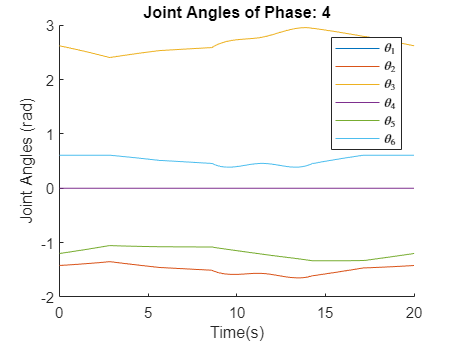

The amount of via points used in this Phase is: 350

time_prev = time(end);
time = [time, plotThetas(theta4, 20, 4)+time_prev];

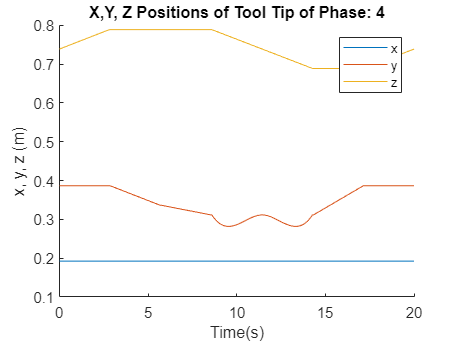

plotxyz(theta4, 20, 4);

% Third letter: P
Pxy_straight_1 = [0, -0.1;
                0, -0.05;
                0, 0;
                0.075, 0];

Pxy_spline = [0.075, 0;
                0.1, -0.025;
                0.075, -0.05];

Pxy_straight_2 = [0.075, -0.05;
                    0, -0.05];

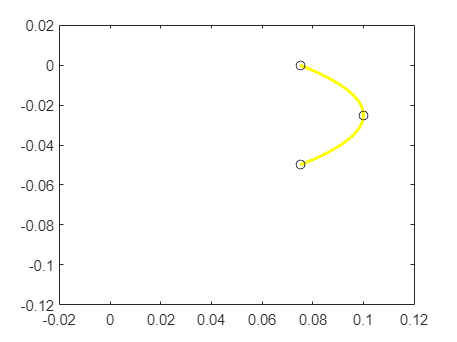

ax_lim_p = [-0.02 0.12 -0.12 0.02];

[px_1, py_1] = plotLines(Pxy_straight_1, 50);
[px_2, py_2] = plotLetter(Pxy_spline, 50, ax_lim_p);

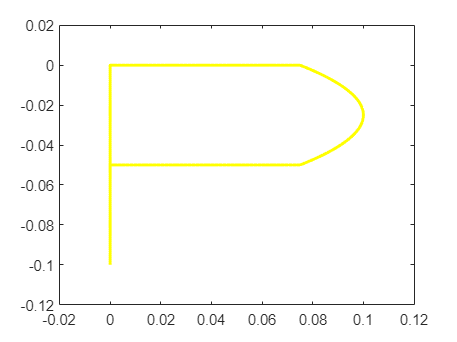

[px_3, py_3] = plotLines(Pxy_straight_2, 50);
px = [px_1, px_2, px_3];
py = [py_1, py_2, py_3];
plotScript(px, py, ax_lim_p);

%Phase 5: Transition from letter B to P
Tr5xy1 = [bx(end), by(end);
         0, 0];
[tr5x1, tr5y1] = plotLines(Tr5xy1, 50);

theta5 = [];
for i=1:length(tr5x1)
    Px = 0; Py = tr5x1(i) ; Pz = tr5y1(i);
    P_now = [Px; Py; Pz];
    theta_now = IKPuma3(P_now, P0_corner, 0.4318, -0.0203, 0.2435, -0.0934, 0.4331, 2);
    theta5 = [theta5; theta_now];
    P = [P P_now];
    [positionErrorNow, orientationErrorNow] = calculatePositionError(theta_now, P_now, P0_corner, 2);
    positionError = [positionError, positionErrorNow];
    orientationError = [orientationError, orientationErrorNow];
end

theta5 = [theta5; JSTrajectory1(2, 3, P0_corner, 50)];

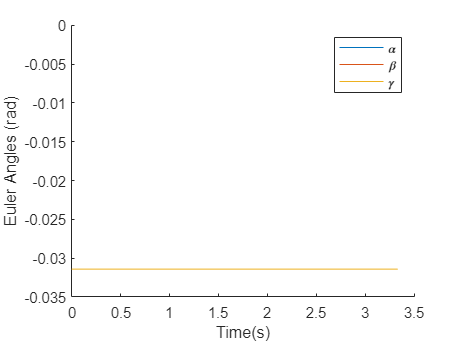

plotEulerAngles(2,3, 10/3);

Tr5xy2 = [0, 0;
         px(1), py(1)];
[tr5x2, tr5y2] = plotLines(Tr5xy2, 50);

for i=1:length(tr5x2)
    Px = tr5x2(i); Py = 0; Pz = tr5y2(i);
    P_now = [Px; Py; Pz];
    theta_now = IKPuma3(P_now, P0_corner, 0.4318, -0.0203, 0.2435, -0.0934, 0.4331, 3);
    theta5 = [theta5; theta_now];
    P = [P P_now];
    [positionErrorNow, orientationErrorNow] = calculatePositionError(theta_now, P_now, P0_corner, 3);
    positionError = [positionError, positionErrorNow];
    orientationError = [orientationError, orientationErrorNow];
end

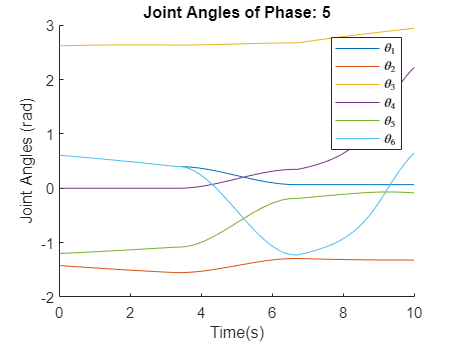

The amount of via points used in this Phase is: 150

time_prev = time(end);
time = [time, plotThetas(theta5, 10, 5)+time_prev];

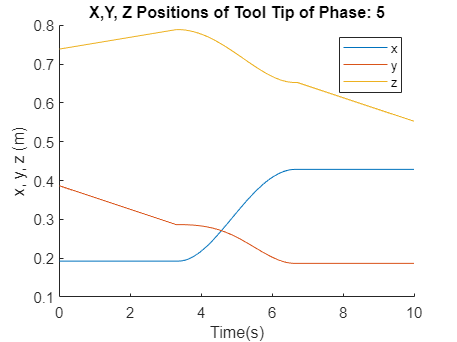

plotxyz(theta5, 10, 5);

% Phase 6 : Trace the second letter P
theta6 = [];
for i=1:length(px)
    Px = px(i); Py = 0; Pz = py(i);
    P_now = [Px; Py; Pz];
    theta_now = IKPuma3(P_now, P0_corner, 0.4318, -0.0203, 0.2435, -0.0934, 0.4331, 3);
    theta6 = [theta6; theta_now];
    P = [P P_now];
    [positionErrorNow, orientationErrorNow] = calculatePositionError(theta_now, P_now, P0_corner, 3);
    positionError = [positionError, positionErrorNow];
    orientationError = [orientationError, orientationErrorNow];
end

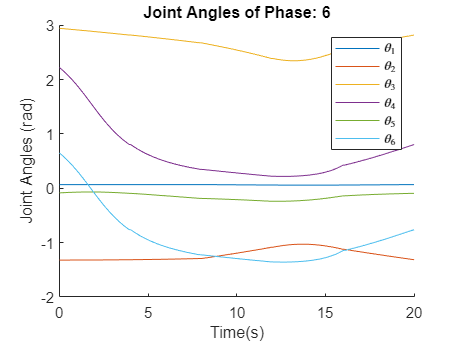

The amount of via points used in this Phase is: 250

time_prev = time(end);
time = [time, plotThetas(theta6, 20, 6)+time_prev];

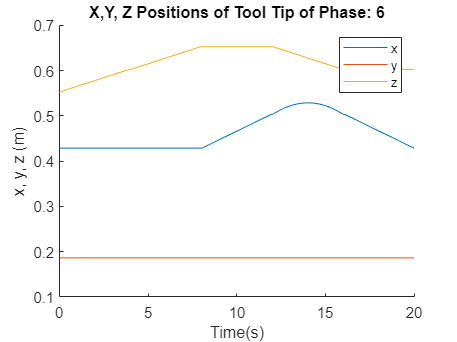

plotxyz(theta6, 20, 6);

% Phase 7: Letter P to the Corner
Tr7xy1 = [px(end), py(end);
         0, 0];
[tr7x1, tr7y1] = plotLines(Tr7xy1, 50);

theta7 = [];
for i=1:length(tr7x1)
    Px = tr7x1(i); Py = 0; Pz = tr7y1(i);
    P_now = [Px; Py; Pz];
    theta_now = IKPuma3(P_now, P0_corner, 0.4318, -0.0203, 0.2435, -0.0934, 0.4331, 3);
    theta7 = [theta7; theta_now];
    P = [P P_now];
    [positionErrorNow, orientationErrorNow] = calculatePositionError(theta_now, P_now, P0_corner, 3);
    positionError = [positionError, positionErrorNow];
    orientationError = [orientationError, orientationErrorNow];
end


theta7 = [theta7; JSTrajectory1(3, 1, P0_corner, 50)];

theta7 = [theta7; JSTrajectory2(theta_corner, theta0, 50)];

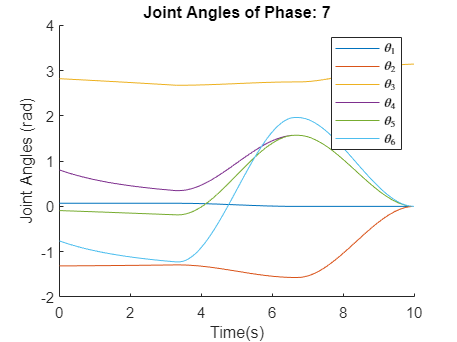

The amount of via points used in this Phase is: 150

time_prev = time(end);
time = [time, plotThetas(theta7, 10, 7)+time_prev];

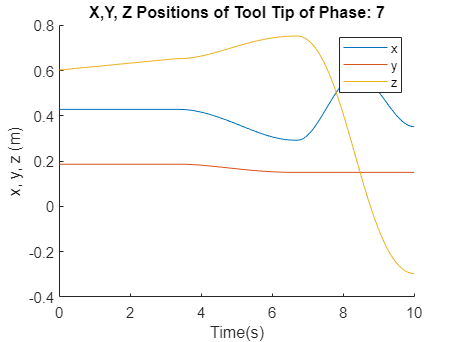

plotxyz(theta7, 10, 7);

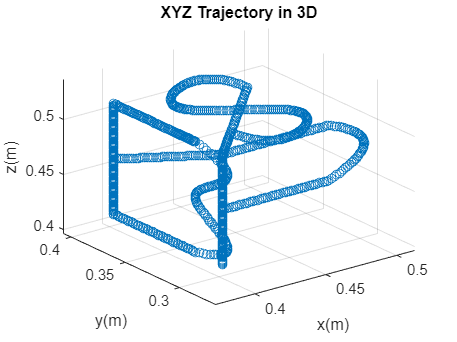

P(1,:) = P(1,:)+P0_corner(1); 
P(2,:) = P(2,:)+P0_corner(2);
P(3,:) = P(3,:)+P0_corner(3);
scatter3(P(1,:),P(2,:),P(3,:))
axis([-0.02+P0_corner(1) 0.12+P0_corner(1) -0.02+P0_corner(2) 0.12+P0_corner(2) -0.12+P0_corner(3) 0.02+P0_corner(3)])
xlabel('x(m)')
ylabel('y(m)')
zlabel('z(m)')
title('XYZ Trajectory in 3D')

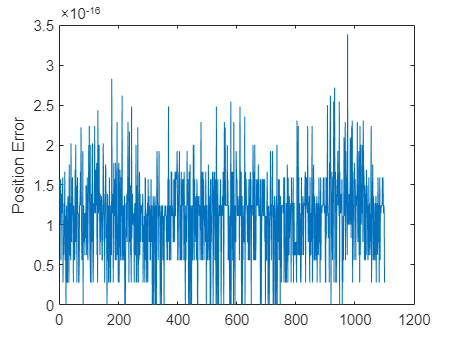

plot(positionError)
ylabel('Position Error')

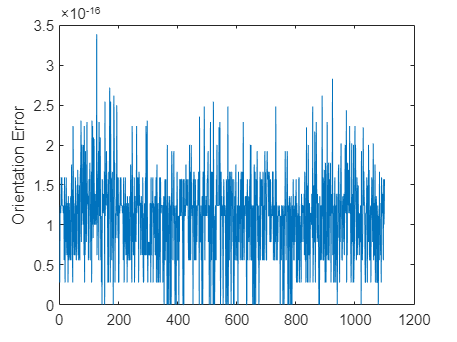

plot(orientationError)
ylabel('Orientation Error')